# MPC Reformulation using Discrete Linear Perturbation Models

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

In the previous lessons,  we have developed a linear perturbation model of the form 

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$ -----(1) 

in the neighborhood of the operating point ($X_s ,U_s$) starting from the nonlinear dynamic model. We have also compared linear and nonlinear model simulations and observed that the linear perturbation model serves as a reasonably good approximation of the system dynamics. The reason for developing this model was to simplify computations of the moving horizon optimal control problem [MHOPC-2.](matlab:open('./L01_MPC Reformulation using Linear Perturbation Model .mlx')) Thus, in this lesson we first reformulate MHOPC-2 using the linear perturbation model (1) and convert it to a quadratic programming problem. Subsequently, we demonstrate application of the linear model based constrained and unconstrained formulation on the quadruple tank system. 

**Learning objectives **

- Develop Linear MPC (LMPC) as reformulation of MHOPC-2 using discrete linear perturbation model

- Convert LMPC formulation to a quadratic programming (QP) problem 

- Derive state feedback control law using unconstrained QP-LMPC 

- Demonstrate LMPC, QP-LMPC and state feedback control law using Quadruple Tank Simulations

## **Linear MPC: Reformulation of MHOPC-2**

Let us assume that the system or plant evolves according to equation (1) and we are at the sampling instant k. Then, reformulation of the optimal control problem MHOPC-2 using the discrete time linear approximation can be stated as follows (**LMPC**): 

 $u\left(k\right),\ldotp \ldotp \ldotp \ldotp ,u\left(k+p-1\right)=\underset{u\left(k\right),\ldotp \ldotp \ldotp \ldotp ,u\left(k+p-1\right)}{\arg \;m\textrm{in}}$$\sum_{j=0}^{p-1} \left\lbrack {z\left(k+j+1\right)}^T W_x \;z\left(k+j+1\right)\right\rbrack +\left\lbrack {u\left(k+j\right)}^T W_u u\left(k+j\right)\right\rbrack$ -----(2) 

Subject to system dynamics 

$z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j\right)\;\;\;\;\textrm{for}\;j=0,1,\ldotp \ldotp \ldotp ,p-1\;\textrm{with}\;\textrm{initial}\;\textrm{condition}\;z\left(k\right)=x\left(k\right)$ -----(3) 

and operating constraints

$\;\;{\Delta u}_L \le u\left(k+j\right)-u\left(k+j-1\right)\le {\Delta u}_H \;\;\textrm{for}\;\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$   -----(4)

$u_L \le u\left(k+j\right)\le u_H \;\textrm{for}\;j=0,1,\ldotp \ldotp \ldotp ,p-1$   ------(5)

$x_L \le z\left(k+j\right)\le x_H \;\;\textrm{for}\;\;\;j=1,\ldotp \ldotp \ldotp ,p$   -----(6)

LMPC formulation is an open loop controller that regulates the process at origin of the perturbation state space, i.e. at $X\left(k\right)=X_s$ of the original state space. This modification is expected to reduce the computation time significantly.  

Let us use  MATLAB constrained optimization solver fmincon from Optimization Toolbox to solve **LMPC**. For the purpose of demonstration, we ignore the bounds on states specified by equation (6).  We need to a bit of work to prepare matrices and vectors for communicating constraints to fmincon 

Defining the future input vector $U_f \left(k\right)$ over the future horizon as

$U_f \left(k\right)={\left\lbrack {u\left(k\right)}^T \;{u\left(k+1\right)}^T \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp {u\left(k+p-1\right)}^T \right\rbrack }^T$-------------------(7)

the input bound constraints can be represented as follows 

 $\Psi_u \;u_L \le U_f \left(k\right)\le \Psi_u \;u_H$---------------(8)

where 


$$\Psi_u =\left\lbrack \begin{array}{c}
I\\
I\\
\cdots \\
I
\end{array}\right\rbrack$$


Further the input rate constraints can be represented as follows 

$\Delta U_f \left(k\right)=\left\lbrack \begin{array}{c}
u\left(k\right)-u\left(k-1\right)\\
u\left(k+1\right)-u\left(k\right)\\
\cdots \\
u\left(k+p-1\right)-u\left(k+p-2\right)
\end{array}\right\rbrack =\Psi U_f \left(k\right)-\Psi_0 u\left(k-1\right)$------------(9)

$\Psi_u \;{\Delta u}_L \le \Psi U_f \left(k\right)-\Psi_0 u\left(k-1\right)\le \Psi_u \;{\Delta u}_H$   ------(10)

where

 $\Psi =\left\lbrack \begin{array}{cccc}
I & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
-I & I & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\cdots  & \cdots  & \cdots  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \cdots  & -I & I
\end{array}\right\rbrack$ ;    and $\Psi_0 =\left\lbrack \begin{array}{c}
I\\
\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\cdots \\
\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack 
\end{array}\right\rbrack$   ------(11)

To communicate these constraints to fmincon, these constraints can be expressed in a standard form as follows 

$\mathbf{A}U_f \left(k\right)\le \mathbf{b}\left(k\right)$----------(12)

where 


$$\mathit{\mathbf{A}}=\left\lbrack \begin{array}{cccc}
I &  &  & \\
 & -I &  & \\
 &  & \Psi  & \\
 &  &  & -\Psi 
\end{array}\right\rbrack \;\;\textrm{and}\;\;\;\mathbf{b}\left(k\right)=\left\lbrack \begin{array}{c}
U_H \\
-U_L \\
{\Delta U}_H +\Psi_0 u\left(k-1\right)\\
{-\Delta U}_L -\Psi_0 u\left(k-1\right)
\end{array}\right\rbrack$$


## Constrained LMPC Implementation for Q-Tank Process 

Let us now implement the control law obtained by constrained optimization using equation (2) for [Q Tank process](matlab:open('../2.Quadruple_Tank_Dynamical_Model/L02_DynamicsofMVPRocess.mlx')). 

clear all 
close all
global QTank U_k D_k mpc

**Task 1**: Select the operating point for Q Tank process

operating_pt=1;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

 We then Initialize discrete dynamic model matrices for MPC formulation using the model matrices

% Initialization of linear discrete time model for plant simulation 

phy = QTank.phy ;
gam = QTank.gama_u  ;
[n_st,n_ip] = size(gam) ;

% Set MPC model 
mpc.phy = phy ; mpc.gam = gam ; 
mpc.n_st = n_st ; mpc.n_ip = n_ip ; 

** MPC Tuning Parameters**

**Task 2: **Set the prediction horizon n_pred to 40**.**

mpc.n_pred =40;   % Set the prediction horizon p = n_pred to between 20 to 50. 

**Task 3:** We need to define the **State Weighting Matrix, **$W_x$,   and the **Input Weighting Matrix, **$W_u$. 

 $W_x =\left\lbrack \begin{array}{cccc}
\alpha_1  & 0 & 0 & 0\\
0 & \alpha_2  & 0 & 0\\
0 & 0 & \alpha_3  & 0\\
0 & 0 & 0 & \alpha_4 
\end{array}\right\rbrack$  and  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$ 

Let us say that regulation of levels in Tank 1 and Tank 2 is more important than regulation of levels in Tank 3 and Tank 4.  This can be communicated to the controller by choosing a state weighting matrix as follow 

alpha(1) =10;  alpha(2) = 10;
alpha(3) =2;  alpha(4) = 2; 
disp('State weighting matrix')

State weighting matrix


mpc.Wx= diag(alpha)   % Create a diagonal weighting matrix 

mpc = struct with fields:
       phy: [4×4 double]
       gam: [4×2 double]
      n_st: 4
      n_ip: 2
    n_pred: 40
        Wx: [4×4 double]



disp('Input weighting matrix')

Input weighting matrix


beta(1) =1;  beta(2) =1;
mpc.Wu= diag(beta) 

mpc = struct with fields:
       phy: [4×4 double]
       gam: [4×2 double]
      n_st: 4
      n_ip: 2
    n_pred: 40
        Wx: [4×4 double]
        Wu: [2×2 double]


For the quadruple tank system input voltages are bound between 0 and 5 Volts. Thus, bounds on perturbation inputs, with reference to $U_s$can be defined as follows 

$u_H =\left\lbrack \begin{array}{c}
5\\
5
\end{array}\right\rbrack -U_s \;$  and  $u_L =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack -U_s$

Further, the input rate constraint can be specified as 

${\Delta u}_H =\left\lbrack \begin{array}{c}
0\ldotp 15\\
0\ldotp 15
\end{array}\right\rbrack \;$  and  $u_L =\left\lbrack \begin{array}{c}
-0\ldotp 15\\
-0\ldotp 15
\end{array}\right\rbrack$   

We have written a code that generates matrices needed for specifying input constraints and rate constraints as per equation(8) and equation (9) and finally the A_mat and B_mat as given in equation (12).  We can check the workspace variables A_mat and B_mat

u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] for nonminimum phase and [3.15 3.15] for non-minimum phase
delta_u =0.65;
deluH = delta_u * ones(n_ip,1) ;  % Specify input rate constraints.
deluL = -deluH ;

% Matrices for Inclusion of U constraints

psi_u = [];       % Generation of psi_u matrix
for i = 1:mpc.n_pred
    psi_u = [psi_u; eye(n_ip)];
end
A_mat  = [eye(mpc.n_pred*n_ip);-eye(mpc.n_pred*n_ip)];
F_vec = [ psi_u* u_H; -psi_u* u_L ] ;
B_mat = zeros( 2*mpc.n_pred*n_ip, n_ip) ;

 Inclusion of delta_U constraints:

**Task 4: **Set **include_deltaU flag** to Yes for including delta U constraints


 include_deltaU =0 ;   % Set this flag to 1 for including delta U constraints
 if (include_deltaU )
     % Generation of psi matrix
     psi_mat = diag(ones( n_ip* mpc.n_pred, 1)) - diag( ones(n_ip*(mpc.n_pred-1), 1),-n_ip);

     % Generation of psi_0 matrix
     psi_0_mat = zeros( n_ip*mpc.n_pred,n_ip ) ;
     psi_0_mat(1:n_ip,1:n_ip) = eye(n_ip) ;

     A_mat = [ A_mat ; psi_mat ; - psi_mat ] ;
     F_vec = [F_vec ; psi_u*deluH ; -psi_u*deluL ] ;
     B_mat = [ B_mat ; psi_0_mat ; -psi_0_mat ] ;
 end


Now that we have prepared the necessary matrices for MPC implementation, let us move to simulate the closed loop behavior under the ideal conditions, i.e. plant is simulated using discrete linear model and the system states are assumed to be perfectly measured. 

###  Closed loop simulations using LMPC under ideal conditions

The optimum controller output is obtained by  MATLAB constrained optimization solver [fmincon from Optimization Toolbox](https://in.mathworks.com/help/optim/ug/fmincon.html) 

**Task 5**: Set the simulation run time N to 101. 

N = 101 ;      % Simulation run time

Uf_k0 = zeros(n_ip*mpc.n_pred,1) ;   % Initial input over the prediction horizon

% Create Matrices to save system states and inputs  

xk = zeros(n_st,N);   
uk = zeros(n_ip,N) ;  
xk(:,1) = [4 -4 2 -2]';   % Initial state is away from the origin 
time_log = zeros(N,1);  % preallocate
options = optimoptions('fmincon','Algorithm','sqp', 'display', 'off')  ;  % Set options for fmincon function

**Task 6: **Set the **Plant_Sim** option to Linear for Quadruple tank Plant Simulation from$\left\lbrack k\;k+1\right\rbrack$ is using discrete linear model $x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$  or Nonlinear for simulation using nonlinear ODE model. (The model is available in the function **QTank_Dynamics**)

 Since we have already seen the controller performance for a linear discrete time model, we can start by setting to Nonlinear simulation.

Plant_Sim =1 ; 

for k = 1:N-1
    tic
    % Controller calculations at instant k assuming state vector is perfectly measured 
    kT(k) = (k-1);
    mpc.xk = xk(:,k) ;  % Initialize global variable for communicating to objective function 

     if (include_deltaU )
        if (k > 2 )
            b_vec = F_vec+B_mat*uk(:,k-1);
        else
            b_vec = F_vec +B_mat*zeros(n_ip,1) ;
        end
    else
        b_vec = F_vec ;
     end
      
    [Uf_k, fval] = fmincon(@LMPC_Cost_fun,Uf_k0,A_mat,b_vec,[],[],[],[],[], options) ;
    time_log(k) = toc;
    mpc.uk = Uf_k(1:n_ip) ;  % Implement only optimal u(k) 
    Uf_k0 = [Uf_k(n_ip+1:end) ; Uf_k((mpc.n_pred-1)*n_ip+1:end) ]  ;
    uk(:,k) = mpc.uk ;
    if (Plant_Sim )
         % Linear plant simulation
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k)  ;
    else
         % Nonlinear plant simulation
        U_k = QTank.Us +uk(:,k);
        D_k =  QTank.Ds ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;  
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    
end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;

% ---- MPC cost function required for fmincon ----- 

function obj_fn = LMPC_Cost_fun( Uf )

global mpc 
persistent zk uk_pred 

% Initialize the future state predictions 
zk = zeros(mpc.n_st,mpc.n_pred);   
zk(:,1) = mpc.xk ;

% Map input guess vector to a matrix with columns as future inputs 
uk_pred = reshape(Uf, [mpc.n_ip,mpc.n_pred])   ;

obj_fn = 0 ;

% Future predictions using 
for j = 1 : mpc.n_pred-1
    zk(:,j+1) = mpc.phy * zk(:,j) + mpc.gam * uk_pred(:,j) ;
    obj_fn = obj_fn + zk(:,j+1)' * mpc.Wx * zk(:,j+1) ;
    obj_fn = obj_fn + uk_pred(:,j)' * mpc.Wu * uk_pred(:,j)  ;
end

end 

**Controller Performance**

The Model Predictive Control (MPC) Performance Index (PI) is a numerical measure of control quality that quantifies how well the MPC achieves its objectives over a given time horizon.

Let us define a closed loop performance index motivated by the MPC cost function as follows 


$$\textrm{PI}\equiv \sum_{k=0}^N \left\lbrack {x\left(k\right)}^T W_x x\left(k\right)+{u\left(k\right)}^T W_u u\left(k\right)\right\rbrack$$


where N represents the simulation time. This PI can be used to compare performances of controllers that we developed in this lesson. Also the average time required for computation is extremely important for online implementation.

**Task 7:** Note down the average time required for controller implementation using fmincon **(avg_time_LMPC)**. PI in indicated by** fval_LMPC**

fval_LMPC = 0 ;
for k = 1:N-1
    fval_LMPC=fval_LMPC+ xk(:,k)' * mpc.Wx* xk(:,k) ;
    fval_LMPC=fval_LMPC+uk(:,k)' * mpc.Wu* uk(:,k) ;
end
avg_time_LMPC = mean(time_log);
disp(['Average computation time LMPC: ', num2str(avg_time_LMPC), ' s']);

Average computation time LMPC: 0.29746 s


disp(['LMPC Cost Function: ', num2str(fval_LMPC)]);

LMPC Cost Function: 1482.2381


**Display Simulation Results **

Now we present the closed loop simulation results, that show the state and input profiles plotted against time. 

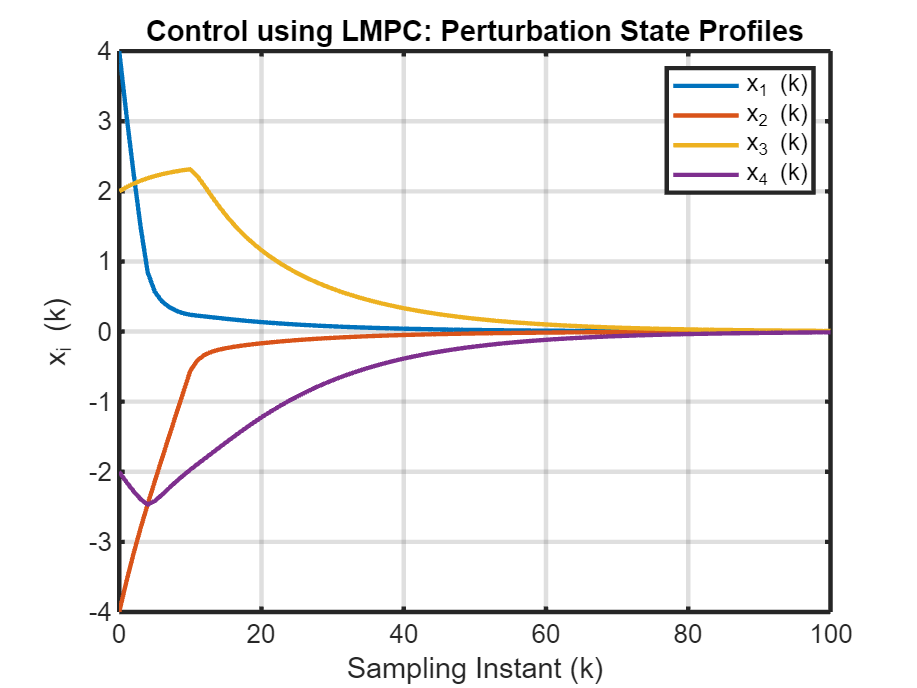

Set_Graphics_Parameters ;   % This script file sets font size and line thickness for figures 

U_limits = [u_L(1)*ones(N,1) u_H(1)*ones(N,1)]  ;  % Matrix to plot input constraint limits 

figure, plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)'), title('Control using LMPC: Perturbation State Profiles')

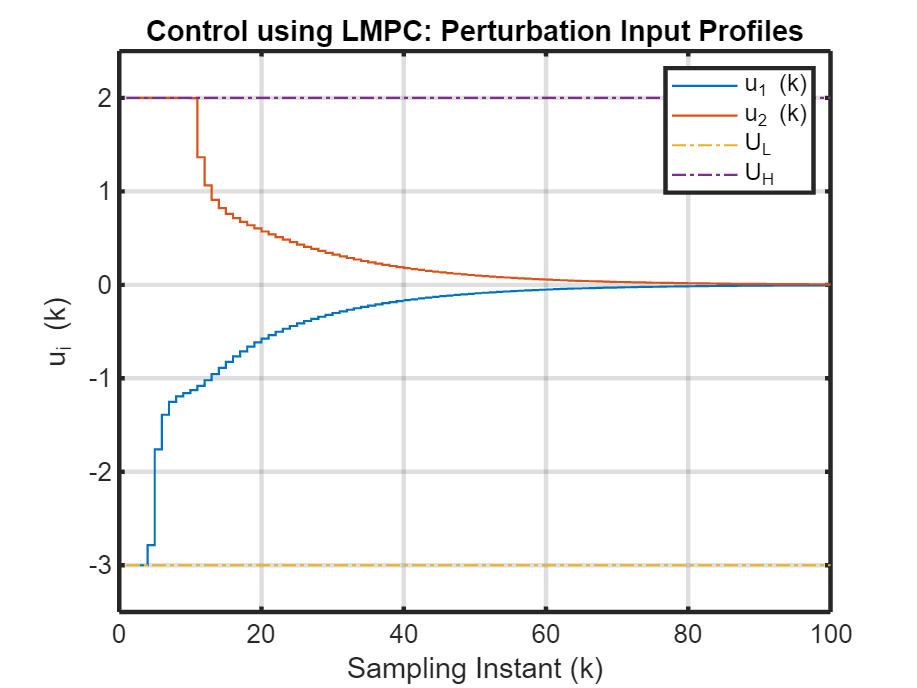

figure, stairs(uk', 'LineWidth',1), grid
hold on 
stairs(U_limits, '-.', 'LineWidth',1)
hold off
axis([0 100 -3.5 2.5])
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), title('Control using LMPC: Perturbation Input Profiles')
legend('u_1 (k)', 'u_2 (k)', 'U_L', 'U_H')

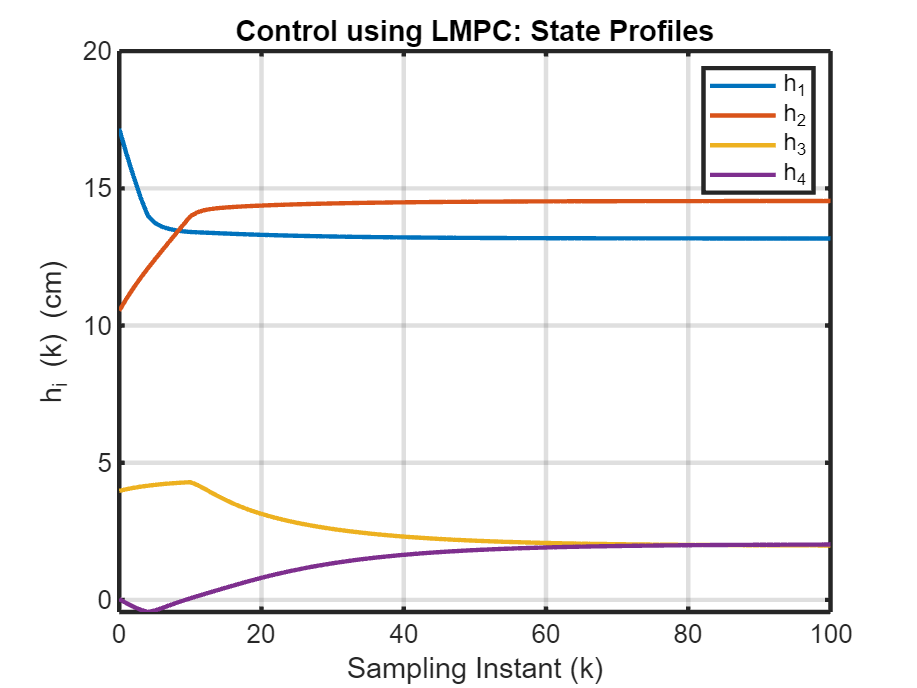

Xk = QTank.Xs + xk ; 
figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('h_i (k) (cm)')
legend('h_1', 'h_2', 'h_3', 'h_4'), title('Control using LMPC: State Profiles')

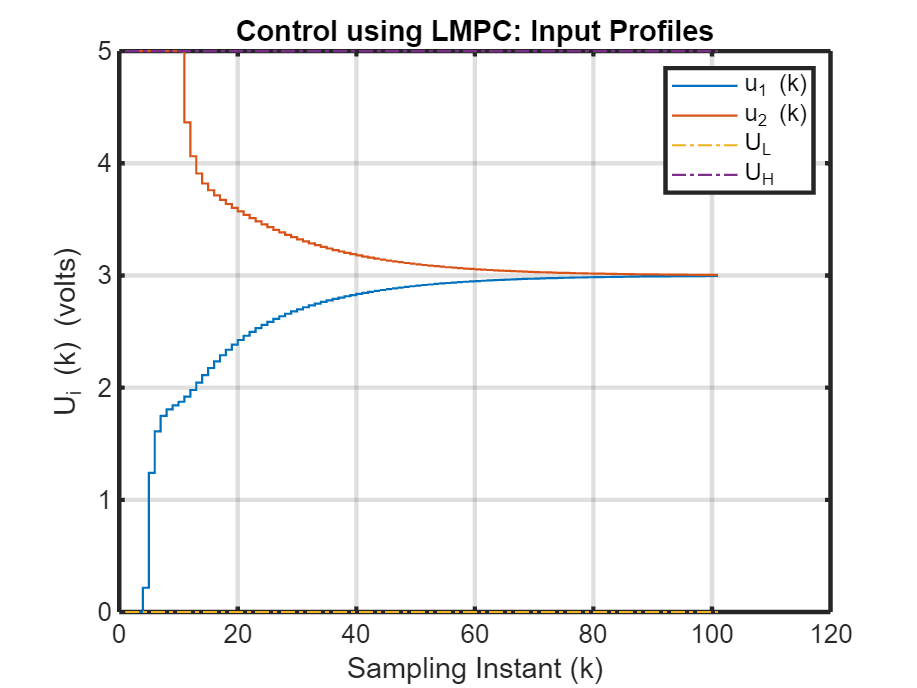

figure, stairs((QTank.Us+uk)', 'LineWidth',1), grid
hold on 
stairs(U_limits+QTank.Us', '-.', 'LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('U_i (k) (volts)'), title('Control using LMPC: Input Profiles')
legend('u_1 (k)', 'u_2 (k)', 'U_L', 'U_H')

Observe that the states are driven to the origin, irrespective of the initial condition.The controller outputs are within the specified upper and lower limits. 

**Task 8:** Now change the operating point and again observe the results.

**Task 9: **Go to Task 2 and try changing the prediction horizon. Observe the effect on results

**Task 10: **Go to Task 3 and try changing the weighting matrices. Observe the effect on results

In the next section, we will reformulate the LMPC as a quadratic programming problem.

## Reformulation of LMPC as a Quadratic Programming Problem

    The use of fmincon function from Optimization Toolbox Optimization Toolbox of MATLAB is an inefficient way to solve the LMPC problem. This is because ***fmincon ***uses sequential quadratic programming for solving the constrained problem, which is an overkill. In this section, we show how model linearity can be exploited to derive a single QP problem, which can be solved far more efficiently than using SQP. 

Using the prediction model repeatedly over the prediction horizon, we can write 

$z\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$  -----(13)

$z\left(k+2\right)=\Phi z\left(k+1\right)+\Gamma u\left(k+1\right)=\Phi^2 x\left(k\right)+\Phi \Gamma u\left(k\right)+\Gamma u\left(k+1\right)$  -----(14)

$z\left(k+3\right)=\Phi z\left(k+2\right)+\Gamma u\left(k+2\right)=\Phi^3 x\left(k\right)+\Phi \Gamma u\left(k\right)+\Gamma u\left(k+1\right)+\Phi^2 \Gamma u\left(k\right)+\Phi \Gamma u\left(k+1\right)+\Gamma u\left(k+2\right)$  -----(15)

Proceeding in a similar matter, we can derive an expression for j-step ahead prediction

$z\left(k+j\right)=\Phi^j x\left(k\right)+\Phi^{j-1} \Gamma u\left(k\right)+\Phi^{j-2} \Gamma u\left(k+1\right)+\ldotp \ldotp \ldotp \ldotp \ldotp +\Gamma u\left(k+j-1\right)$------(16)

Defining the future input vector $U_f \left(k\right)$ and the predicted output vector $X_p \left(k\right)$) over the future horizon as

$U_f \left(k\right)={\left\lbrack {u\left(k\right)}^T \;{u\left(k+1\right)}^T \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp {u\left(k+p-1\right)}^T \right\rbrack }^T$-------------------(16)

$Z_p \left(k\right)={\left\lbrack {z\left(k+1\right)}^T \;{z\left(k+2\right)}^T \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp {z\left(k+p\right)}^T \right\rbrack }^T$-------------------(17)

the prediction model over the entire prediction horizon given by equation (3) can be expressed as a single matrix expression 

$Z_p \left(k\right)=S_x x\left(k\right)+S_u U_f \left(k\right)$  -----(18) 

where

$S_x =\left\lbrack \begin{array}{c}
\Phi \\
\Phi ²\\
\cdots \\
\Phi^p 
\end{array}\right\rbrack \;\;\;\textrm{and}\;\;\;S_u =\left\lbrack \begin{array}{cccc}
\Gamma  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp \ldotp  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\Phi \Gamma  & \Gamma  &  & \\
\ldotp \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \ldotp \\
\Phi^{p-1} \Gamma  & \Phi^{p-2} \Gamma  & \ldotp \ldotp \ldotp \ldotp  & \Gamma 
\end{array}\right\rbrack$    -------(19)

Here $\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack$ represent null matrices of dimension $n\times m$. Defining block diagonal matrices 

${\mathbf{W}}_X =\left\lbrack \begin{array}{cccc}
W_x  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp  & \left\lbrack 0\right\rbrack \\
\left\lbrack 0\right\rbrack  & W_x  & \ldotp \ldotp \ldotp  & \left\lbrack 0\right\rbrack \\
 &  & \ddots  & \\
\left\lbrack 0\right\rbrack  & \left\lbrack 0\right\rbrack  & \ldotp \ldotp \ldotp  & W_x 
\end{array}\right\rbrack \;\;\;\textrm{and}\;\;\;{\mathbf{W}}_U =\left\lbrack \begin{array}{cccc}
W_u  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp  & \left\lbrack 0\right\rbrack \\
\left\lbrack 0\right\rbrack  & W_u  & \ldotp \ldotp \ldotp  & \left\lbrack 0\right\rbrack \\
 &  & \ddots  & \\
\left\lbrack 0\right\rbrack  & \left\lbrack 0\right\rbrack  & \ldotp \ldotp \ldotp  & W_u 
\end{array}\right\rbrack$ 	  ------(20)

the quadratic cost function (2)  in LMPC can be rewritten as follows 

$\varphi ={Z_p \left(k\right)}^T {\mathbf{W}}_X Z_p \left(k\right)+{U_f \left(k\right)}^T {\mathbf{W}}_U U_f \left(k\right)$ -----(21)

Combining with equation (13), we can write the cost function as a quadratic function of $U_f \left(k\right)$ as follows 

${\varphi =\left(S_x x\left(k\right)+S_u U_f \left(k\right)\right)}^T {\mathbf{W}}_X \left(S_x x\left(k\right)+S_u U_f \left(k\right)\right)+{U_f \left(k\right)}^T {\mathbf{W}}_U U_f \left(k\right)$ ------(22)

Collecting linear and quadratic terms in $U_f \left(k\right)$, equation (17) can be rearranged as follows 

$\varphi \;\;\;={U_f \left(k\right)}^T \left({S_u }^T {\mathbf{W}}_X S_u +{\mathbf{W}}_U \right)U_f \left(k\right)+{2x\left(k\right)}^T \;\left({S_x }^T {\mathbf{W}}_X S_u \right)U_f \left(k\right)+Q\left(x\left(k\right)\right)$-----(23)

where $Q\left(x\left(k\right)\right)={x\left(k\right)}^T \left({{\;S}_x }^T {\mathbf{W}}_X S_x \right)x\left(k\right)$. Note the $Q\left(x\left(k\right)\right)$ is not influenced by $U_f \left(k\right)$ and can be dropped. Thus, we can minimize the following modified cost function 

$\varphi \;\;\;=\frac{1}{2}{{\;U}_f \left(k\right)}^T \;\mathbf{H}\;U_f \left(k\right)+{F\left(k\right)}^T U_f \left(k\right)$  -----(24a) 

$\mathbf{H}=2\left({S_u }^T {\mathbf{W}}_X S_u +{\mathbf{W}}_U \right)\;\textrm{and}\;\;F\left(k\right)=2\left({{S_u }^T \mathbf{W}}_X S_x \right)\;x\left(k\right)=\mathit{\mathbf{F}}\;\mathit{\mathbf{x}}\left(k\right)$------(24b)

We can express operating constraints as follows 

$\Psi_u \;u_L \le U_f \left(k\right)\le \Psi_u \;u_H$  ------(25)

$\Psi_u \;{\Delta u}_L +\Psi_0 u\left(k-1\right)\le \Psi U_f \left(k\right)\le \Psi_u \;{\Delta u}_H +\Psi_0 u\left(k-1\right)$ ------(26)

$X_L -S_x x\left(k\right)\le S_u U_f \left(k\right)\le X_H -S_x x\left(k\right)$  ------(27)

where 

 
$$\;X_L =\left\lbrack \begin{array}{c}
x_L \\
\ldotp \ldotp \ldotp \ldotp \\
x_L 
\end{array}\right\rbrack \;\;;\;\Delta U_H =\left\lbrack \begin{array}{c}
x_H \\
\ldotp \ldotp \ldotp \ldotp \\
x_H 
\end{array}\right\rbrack \;\;$$


These operating constraints can be expressed in a standard form as follows 

$\mathbf{A}U_f \left(k\right)\le \mathbf{b}\left(k\right)$------------(28)

where 


$$\mathit{\mathbf{A}}=\left\lbrack \begin{array}{cccccc}
I &  &  &  &  & \\
 & -I &  &  &  & \\
 &  & \Psi  &  &  & \\
 &  &  & -\Psi  &  & \\
 &  &  &  & S_u  & \\
 &  &  &  &  & -S_u 
\end{array}\right\rbrack \;\;\;\;\mathrm{and}\;\;\;\mathbf{b}\left(k\right)=\left\lbrack \begin{array}{c}
U_H \\
-U_L \\
{\Delta U}_H +\Psi_0 u\left(k-1\right)\\
{-\Delta U}_L -\Psi_0 u\left(k-1\right)\\
X_H -S_x x\left(k\right)\\
{-X}_L +S_x x\left(k\right)
\end{array}\right\rbrack$$


we can transform LMPC as a quadratic programming (QP) problem as follows (LMPC-QP) 

$U_f^* \left(k\right)=\underset{U_f \left(k\right)}{\arg \;m\textrm{in}}$ $\frac{1}{2}{{\;U}_f \left(k\right)}^T \;\mathbf{H}\;U_f \left(k\right)+{F\left(k\right)}^T U_f \left(k\right)$  ----(29)

Subject to 


$$\mathbf{A}U_f \left(k\right)\le \mathbf{b}\left(k\right)$$


Note that the cost function is quadratic function of the decision vector$U_f \left(k\right)$ and inequality constrains are linear functions of $U_f \left(k\right)$. Very efficient solvers are available for solving such QP problems. In particular, function ***qpsol ***from MATLAB Optimization Toolbox can be used to solve LMPC-QP.  In the moving horizon framework, only the first optimal input move, i.e. ${u\left(k\right)=\;u}^* \left(k\right)$ from the optimal solution $U_f^* \left(k\right)$ is implemented on the plant at instant $k$.  At sampling instant $\left(k+1\right)$, new QP problem is formulated over interval  $\left\lbrack k+1,k+p+1\right\rbrack$ and solved.

### Constrained LMPC-QP Implementation for Quadruple Tank Process

In this exercise, we start with generation of $S_x$ and $S_u$ matrices as given in equation (19). Users can check the variables  Su_mat and  Sx_mat in the workspace.

% Generate Sx and Su matrices 

mat = zeros(n_st, n_ip * mpc.n_pred);
Sx_mat = [] ;     Su_mat = [] ;
WX_mat = [] ;     WU_mat = [] ; 
c2 = 0 ;

for k = 1 : mpc.n_pred
    mat = mpc.phy*mat;  % Block row matrix for intermediate computations 
    
    % Generation of Su_mat   
    c1 = c2 ; c2 = c1 + n_ip ;
    mat(:,c1+1:c2) = mpc.gam;    
    Su_mat = [ Su_mat ; mat ] ;
    
    % Generation of Sx_mat
    Sx_mat = [ Sx_mat ; mpc.phy^k ] ;


The next step is to generate state and input weighting matrices as given in equation (20). Recall that we have set the values for Wx and Wu in Task 3 above.

    WX_mat = blkdiag(WX_mat, mpc.Wx)  ;
    WU_mat = blkdiag(WU_mat, mpc.Wu)  ;   
end

**Task 11: **Generate QP matrices H_mat and F_mat given Su_mat, Sx_mat, WX_mat and WU_mat (Refer equation 24b)

% Generate QP matrices
H_mat = 2 * (Su_mat'* WX_mat * Su_mat + WU_mat ) ;

F_mat = 2 * Su_mat' * WX_mat * Sx_mat ;
H_mat=(H_mat+H_mat')/2;   % This step is to avoid warnings from quadprog 

** Closed loop simulations using LMPC-QP under ideal conditions**

% Create Matrices to save system states and inputs  
xk = zeros(n_st,N);
xk(:,1) = [4 -4 2 -2]';
uk = zeros(n_ip,N) ;
time_log = zeros(N,1);  % preallocate
options=optimoptions('quadprog', 'display', 'off');

for k = 1:N-1
    % Controller calculations at instant k assuming state vector is perfectly measured
    kT(k) = (k-1);
    tic
    if (include_deltaU )
        if (k > 2 )
            b_vec = F_vec+B_mat*uk(:,k-1);
        else
            b_vec = F_vec +B_mat*zeros(n_ip,1) ;
        end
    else
        b_vec = F_vec ;
    end
    mpc.xk = xk(:,k) ;   % Plant state is perfectly measured

    f_vec = F_mat*mpc.xk;

**Task 12:**  We will now compute the optimal controller output using MATLAB function [quadprog](https://in.mathworks.com/help/optim/ug/quadprog.html). [x, fval]= quadprog(H,f,A,b,[],[],[],[],[], OPTIONS). Use inputs as **H_mat, f, A_mat, b_vec and outputs as U, FVAL**

    [Uf_k,fval] = quadprog(H_mat, f_vec, A_mat, b_vec,[],[],[],[],[],options) ;
    time_log(k) = toc;
    mpc.uk = Uf_k(1:n_ip) ;  % Implement only optimal u(k)
    uk(:,k) = mpc.uk ;

Quadruple tank Plant Simulation from$k\;\textrm{to}\;k+1$is done using discrete linear model $x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$ or using nonlinear simulation. 

    uk(:,k) = mpc.uk ;
   if (Plant_Sim )

Average computation time LMPC-QP: 0.0027872 s


         % Linear plant simulation
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k)  ;
    else
         % Nonlinear plant simulation
        U_k = QTank.Us + mpc.uk ;
        D_k =  QTank.Ds ;

LMPC-QP Cost Function: 1482.2381


        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;  
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;

**LMPC-QP Controller Performance**

**Task 13:** Note down the time required for controller implementation using QP solver,** (t_QPMPC)** as well as the QPMPC cost function, **fval_QPMPC**. Compare these values with the corresponding values obtained for LMPC in the previous exercise. The computation time is quite small as compared with LMPC computation time however the cost function magnitude does not differ much.

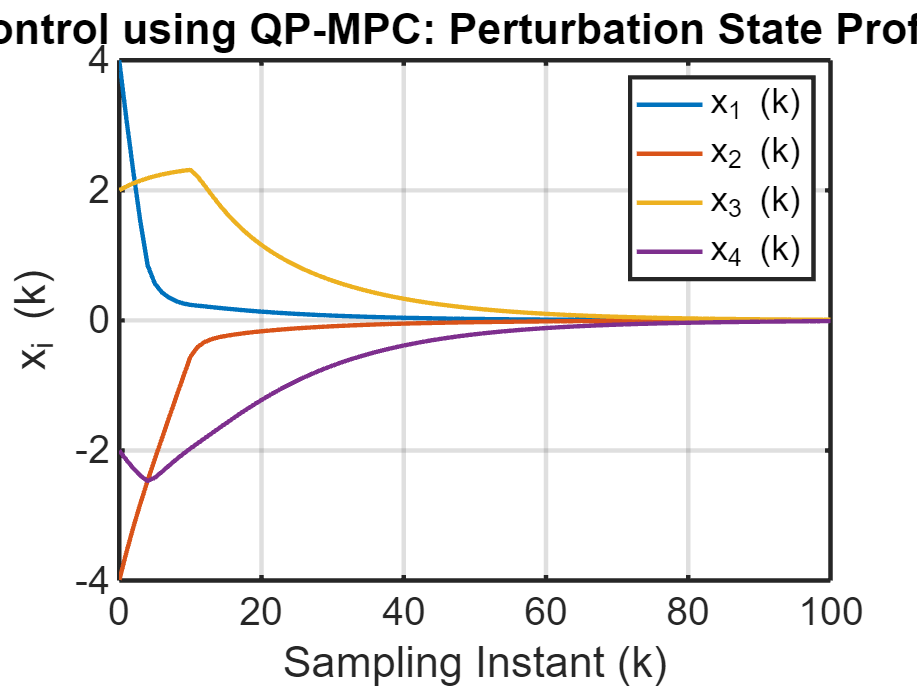

avg_time_LMPC_QP = mean(time_log);

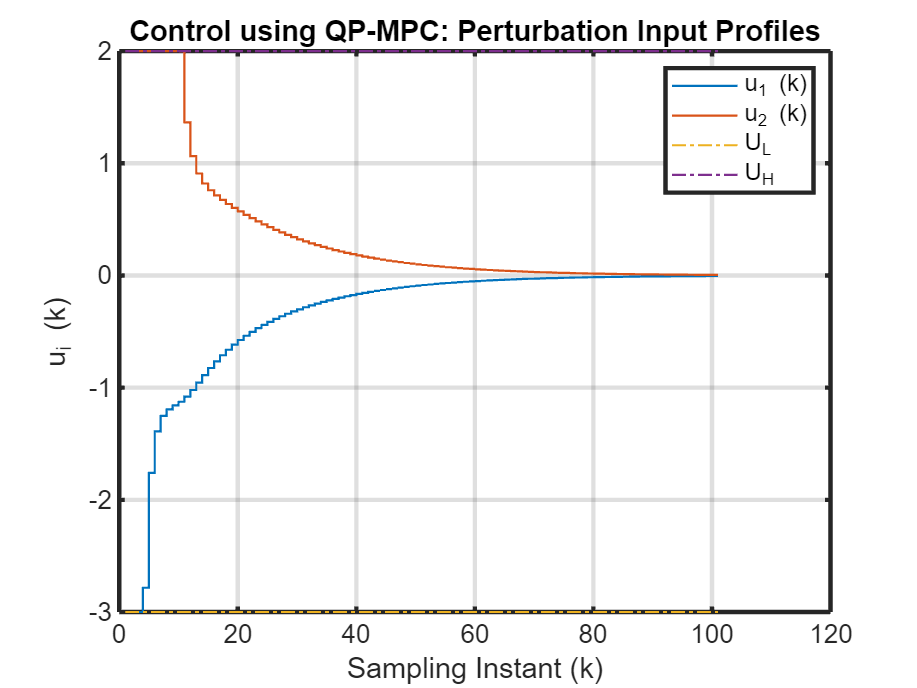

disp(['Average computation time LMPC-QP: ', num2str(avg_time_LMPC_QP), ' s']);
fval_QPMPC = 0;
for k = 1:N-1
    fval_QPMPC=fval_QPMPC+ xk(:,k)' * mpc.Wx* xk(:,k) ;
    fval_QPMPC=fval_QPMPC+uk(:,k)' * mpc.Wu* uk(:,k) ;
end

disp(['LMPC-QP Cost Function: ', num2str(fval_QPMPC)]);


**Simulation Results**

Now observe the simulation results that show the state and input profiles plotted against time. Observe that the states are driven to the origin, irrespective of the initial condition.The controller outputs are within the specified upper and lower limits.

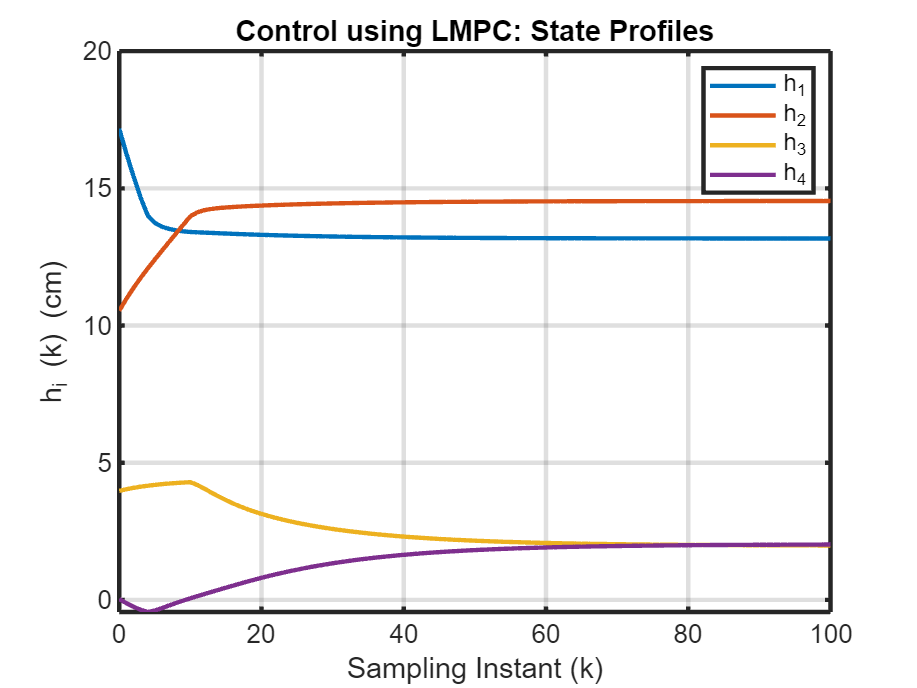

U_limits = [u_L(1)*ones(N,1) u_H(1)*ones(N,1)]  ;
figure, plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid

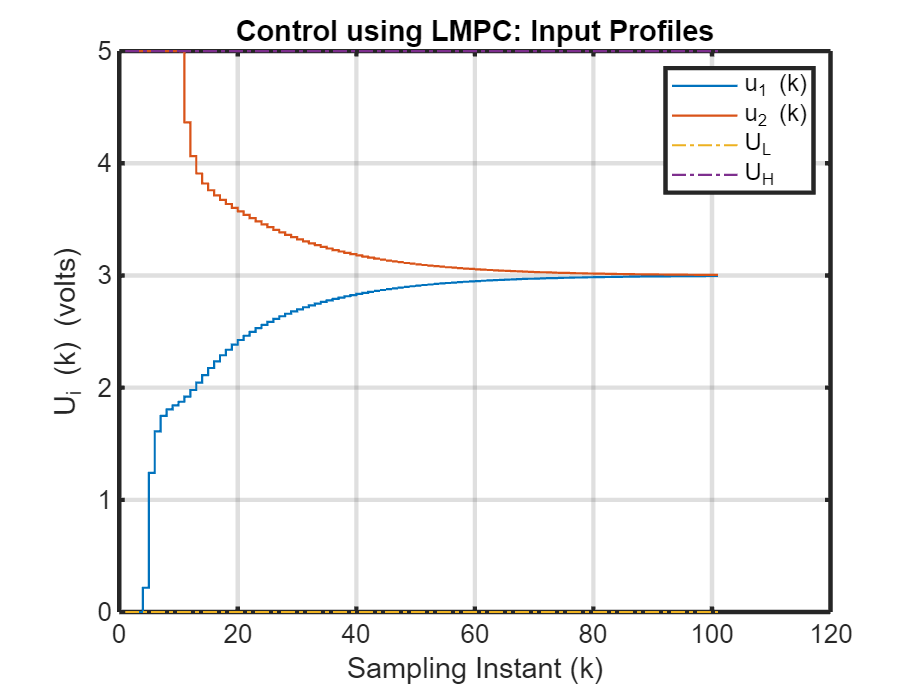

xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)'), title('Control using QP-MPC: Perturbation State Profiles')
figure, stairs(uk', 'LineWidth',1), grid
hold on 
stairs(U_limits, '-.', 'LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), title('Control using QP-MPC: Perturbation Input Profiles')

legend('u_1 (k)', 'u_2 (k)', 'U_L', 'U_H')
Xk = QTank.Xs + xk ; 
figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('h_i (k) (cm)')
legend('h_1', 'h_2', 'h_3', 'h_4'), title('Control using LMPC: State Profiles')

figure, stairs((QTank.Us+uk)', 'LineWidth',1), grid
hold on 
stairs(U_limits+QTank.Us', '-.', 'LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('U_i (k) (volts)'), title('Control using LMPC: Input Profiles')
legend('u_1 (k)', 'u_2 (k)', 'U_L', 'U_H')

Thus we can see that the states are brought to zero starting from a non-zero initial state and the controller outputs are withing the bounds, similar to LMPC. Note that the average computation time has reduced to a great extent, indicating that QP formulation is better suited for online controller implementation. 

**Task 14:** Now change the operating point and again observe the results.

**Task 15: **Go to Task 2 and try changing the prediction horizon. Observe the effect on results

**Task 16: **Go to Task 3 and try changing the weighting matrices. Observe the effect on results

In the next section, we will see the performance of unconstrained LMPC.

## Unconstrained LMPC 

    If we ignore the bound constraints and consider an unconstrained optimization problem

$\min_{U_f \left(k\right)} \;\left({{\varphi =0\ldotp 5\;U}_f \left(k\right)}^T \mathbf{H}U_f \left(k\right)+{U_f \left(k\right)}^T F\left(k\right)\right)$---------(30)

The unconstrained optimum for this problem can be found by using the necessary condition for optimality, i.e. 

$\frac{\partial \varphi }{\partial U_f \left(k\right)}=$$\mathbf{H}U_f \left(k\right)+F\left(k\right)=0$-----------(31)

Thus the optimum input vector is given by 

$U_f^* \left(k\right)=-H^{-1} F\left(k\right)$ = $\;-\;\left\lbrack {\left({S_u }^T {\mathbf{W}}_X S_u +{\mathbf{W}}_U \right)}^{-1} \left({\mathbf{W}}_X S_x \right)\right\rbrack x\left(k\right)$------(32)

Since only the first input move is implemented on the process

${u\left(k\right)=\;u}^* \left(k\right)={\Lambda_0 }^T U_f \left(k\right)=-{\Psi_0 }^T \left\lbrack {\left({S_u }^T {\mathbf{W}}_X S_u +{\mathbf{W}}_U \right)}^{-1} \left({S_u }^T \;{\mathbf{W}}_X S_x \right)\right\rbrack x\left(k\right)$-------(33)

Defining gain matrix 

$G_{\textrm{MPC}} ={\Psi_0 }^T \left\lbrack {\left({S_u }^T {\mathbf{W}}_X S_u +{\mathbf{W}}_U \right)}^{-1} \left({S_u }^T \;{\mathbf{W}}_X S_x \right)\right\rbrack$----(34)

we arrive at a state feedback control law of the form

 $u\left(k\right)=-{\;G}_{\textrm{MPC}} \;x\left(k\right)$-------(35)

Advantage of the unconstrained LMPC formulation is that a closed form control law can be derived. There is no iterative numerical scheme (such as QP solver) involved, and, as a consequence, the time required for on-line computations is very small. The flip side is that operating constraints cannot be handled explicitly. This is evident if you run the following unconstrained simulation. Let us now implement this on Q Tank process.

## Unconstrained LMPC for Q tank Process

We will now check how unconstrained MPC controller as given in equation (35) works under ideal conditions (ideal linear plant simulation). The controller gain is computed as given in equation(34)

% Check how unconstrained MPC controller works under ideal conditions (ideal linear plant simulation)  
tic
G_mat_pred = inv(H_mat) * F_mat  ; 
     % Generation of psi_0 matrix
     psi_0_mat = zeros( n_ip*mpc.n_pred,n_ip ) ;
     psi_0_mat(1:n_ip,1:n_ip) = eye(n_ip) ;


**Task 17:** Note down the controller gain G_MPC.

G_MPC = psi_0_mat' * G_mat_pred 

G_MPC =     1.7540   -0.0663    0.3522    0.0973
   -0.0046    1.9572    0.1612    0.3256


**Task 18:** The closed loop eigen values are computed as $\Phi -\Gamma {\;G}_{\textrm{MPC}}$ are as follows. We can see the variable eigen_values in the workspace.

eigen_values=eig(phy - gam*G_MPC)   % Check closed loop eigenvalues

eigen_values =     0.9423
    0.8152
    0.3610
    0.4407


% Closed loop simulations using G_MPC under ideal conditions
xk = zeros(n_st,N);
xk(:,1) = [4 -4 2 -2]';
uk = zeros(n_ip,N) ;
MPC_uk = zeros(n_ip, N) ;
time_log=zeros(N,1);

Closed loop simulations are done using fixed gain control law given in equation (35),  $u\left(k\right)=-{\;G}_{\textrm{MPC}} \;x\left(k\right)$, Quadruple tank Plant Simulation from k to k+1 using discrete linear model or nonlinear simulation

for k = 1:N-1
    kT(k) = (k-1);
    % Control law calculations at instant k
    mpc.xk = xk(:,k) ;  % Plant state is assumed to be known perfectly
    tic
    mpc.uk = - G_MPC * mpc.xk ;
    MPC_uk(:,k) = mpc.uk  ;

    uk(:,k) = mpc.uk  ; % This input is sent to plant after clipping to input bounds 


    if ( uk(1,k) <= u_L(1) )   % Impose input constraints on uk(1)
        uk(1,k) = u_L(1) ;
    elseif ( uk(1,k) >= u_H(1) )
        uk(1,k) = u_H(1) ;
    end
    if ( uk(2,k) <= u_L(2) ) % Impose output constraints on uk(2)
        uk(2,k) = u_L(2) ;
    elseif ( uk(2,k) >= u_H(2) )
        uk(2,k) = u_H(2) ;
    end
    time_log(k)=toc;

    % Quadruple tank Plant Simulation from k to k+1 using discrete linear
    % model or nonlinear simulation
  
    if (Plant_Sim )
        % Linear plant simulation
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k)  ;
    else
        % Nonlinear plant simulation
        U_k = QTank.Us + mpc.uk ;
        D_k =  QTank.Ds ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end

end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;

**Task 19:** Note down the average time required for controller implementation using QP solver. (avg_time_GMPC). It is very very small as compared to the previous controller formulations.

avg_time_GMPC = mean(time_log);
disp(['Average computation time GMPC: ', num2str(avg_time_GMPC), ' s']);

Average computation time GMPC: 2.9037e-05 s


fval_GMPC = 0;
for k = 1:N-1
    fval_GMPC=fval_GMPC+ xk(:,k)' * mpc.Wx* xk(:,k) ;
    fval_GMPC=fval_GMPC+uk(:,k)' * mpc.Wu* uk(:,k) ;
end
disp(['LMPC-QP Cost Function: ', num2str(fval_GMPC)]);

LMPC-QP Cost Function: 1483.1923


**Simulation Results**

Now observe the simulation results that show the state and input profiles plotted against time. Observe that the states are driven to the origin, irrespective of the initial condition.The controller outputs are not within the specified upper and lower limits, as we have not included the bounds in the formulation.

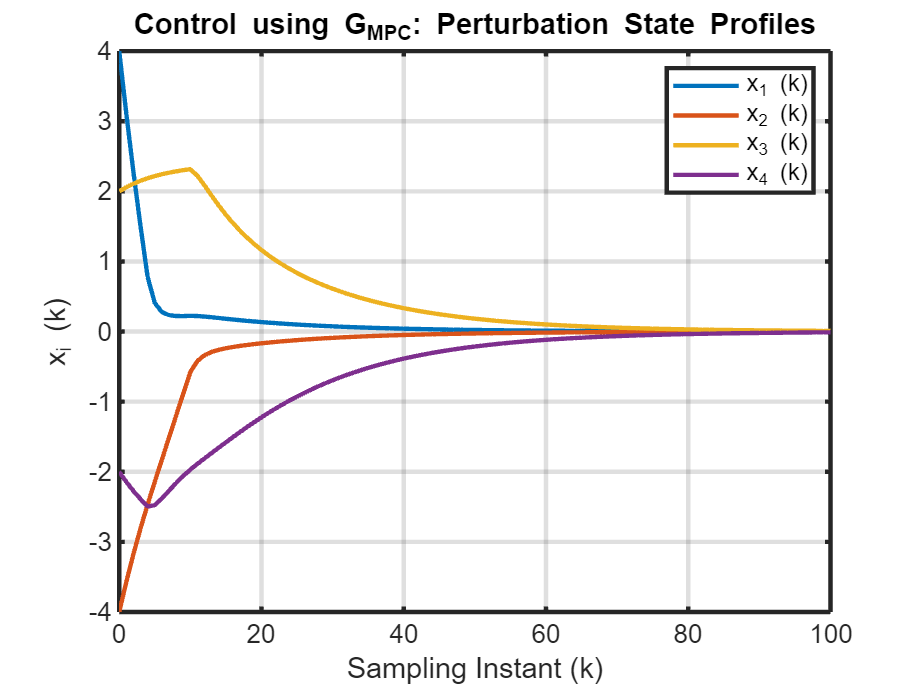

figure, plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)'), title('Control using G_M_P_C: Perturbation State Profiles')

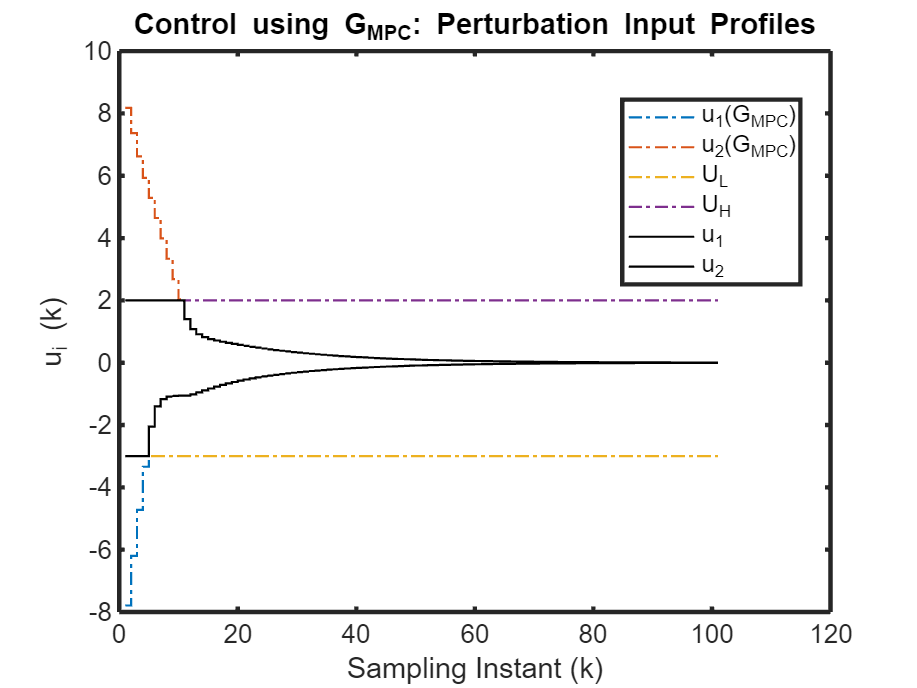

figure, stairs(MPC_uk', '-.', 'LineWidth',1)
hold on 
stairs(U_limits, '-.', 'LineWidth',1)
stairs(uk', 'k', 'LineWidth',1) 
hold off 
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), title('Control using G_M_P_C: Perturbation Input Profiles')
legend('u_1(G_M_P_C)', 'u_2(G_M_P_C)', 'U_L', 'U_H', 'u_1', 'u_2',  'Orientation','vertical', 'Location','best')

k = QTank.Xs + xk ; 
figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('h_i (k) (cm)')
legend('h_1', 'h_2', 'h_3', 'h_4'), title('Control using LMPC: State Profiles')

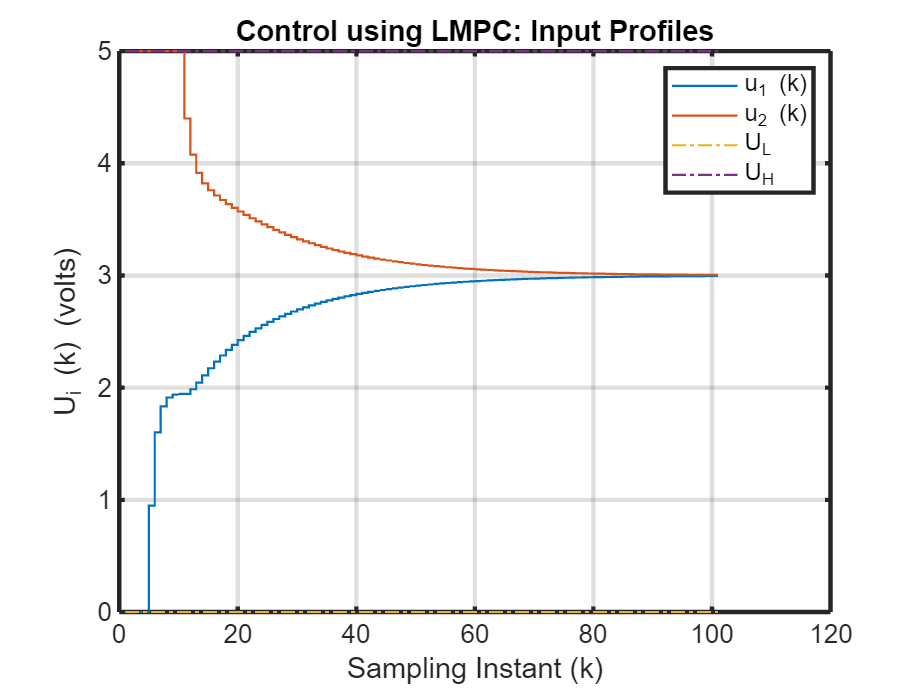


figure, stairs((QTank.Us+uk)', 'LineWidth',1), grid
hold on 
stairs(U_limits+QTank.Us', '-.', 'LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('U_i (k) (volts)'), title('Control using LMPC: Input Profiles')
legend('u_1 (k)', 'u_2 (k)', 'U_L', 'U_H')

Thus we can see that the perturbation states are brought to zero starting from a non-zero initial state but the controller outputs are **not withing the bounds**, as LMPC and QLMPC. Note that the average computation time has reduced to a great extent, as we have a closed form of control law. . 

**Task 20:** Now change the operating point and again observe the results.

**Task 21: **Go to Task 2 and try changing the prediction horizon. Observe the effect on results

**Task 22: **Go to Task 3 and try changing the weighting matrices. Observe the effect on results

**Comparison of Results**

Let us now compare the computation times for LMPC, LMPC-QP and GMPC. There is a drastic reduction in the computation times as we move from LMPC to QP-LMPC and then GMPC, which can be seen in the bar graph.

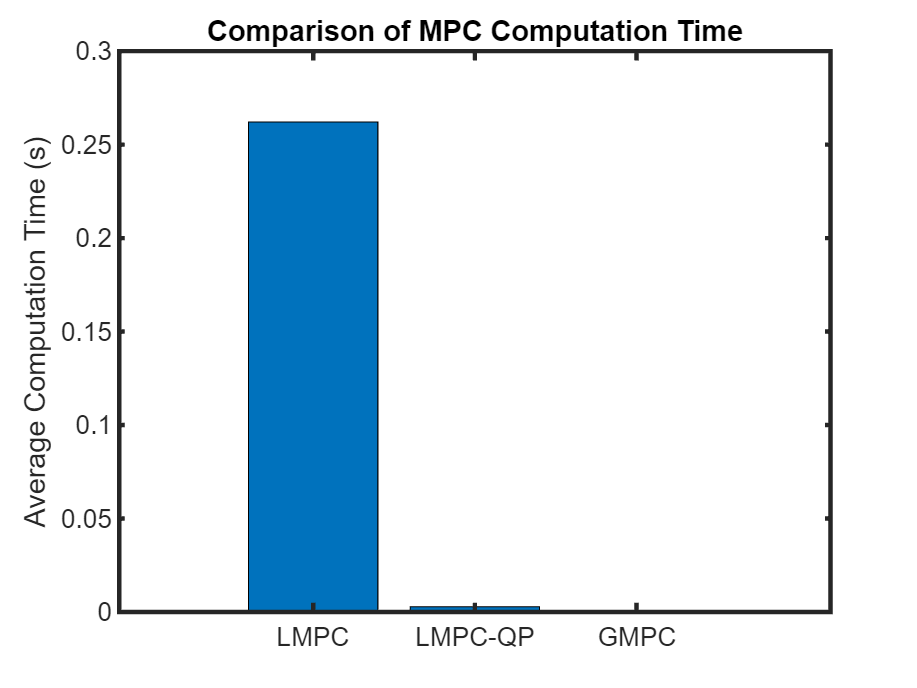

figure
bar([avg_time_LMPC,avg_time_LMPC_QP,avg_time_GMPC])
xticklabels({'LMPC', 'LMPC-QP', 'GMPC'})
ylabel('Average Computation Time (s)')
title('Comparison of MPC Computation Time')

Let us now compare the cost functions for LMPC, LMPC-QP.  We can see that the cost function values do not differ much from each other.

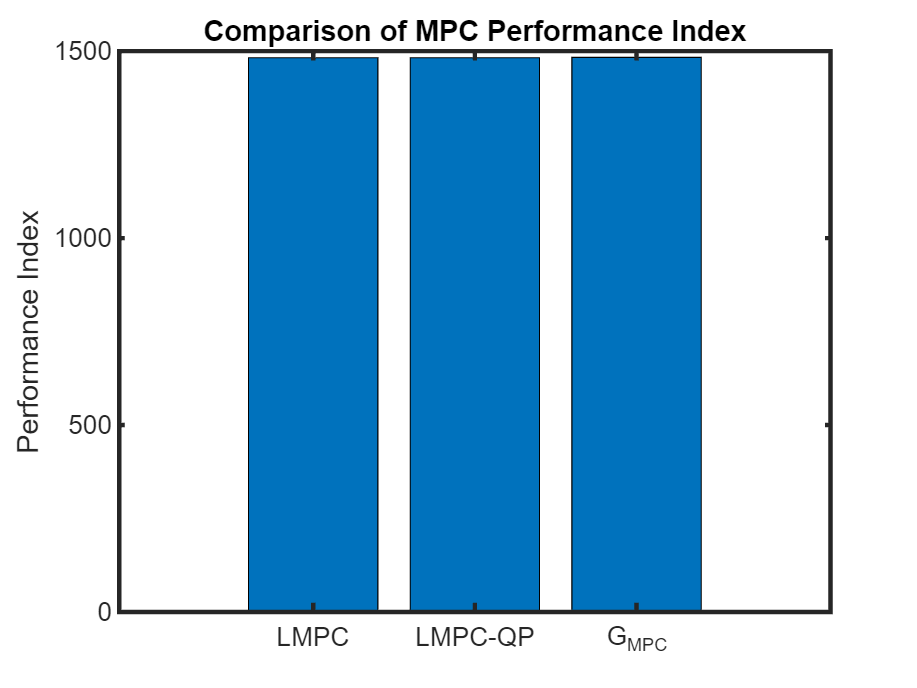

figure
bar([fval_LMPC,fval_QPMPC, fval_GMPC])
xticklabels({'LMPC', 'LMPC-QP', 'G_M_P_C'})
ylabel('Performance Index')
title('Comparison of MPC Performance Index')

## Conclusion

In this lesson, we have developed Linear MPC (LMPC) as reformulation of MHOPC-2  using linear discrete dynamic approximation of the system under consideration.  We have used  MATLAB constrained optimization solver **fmincon** from Optimization Toolbox to solve **LMPC**. Further by exploiting linearity, we have converted the LMPC as a quadratic programming problem (QP-LMPC). MATLAB Optimization Toolbox function ***quadprog***  is used to solve QP-LMPC. We also derive a closed form state feedback control law under unconstrained conditions (i.e. in absence of any bound constraints on inputs and states). Under the ideal conditions (plant dynamics simulated using discrete linear model and plant state is perfectly measured), we demonstrate efficacy of QP-LMPC using Quadruple Tank system. The QP-LMPC is able to honor constraints on inputs and rate of change of inputs while carrying out regulatory control.  While LPMC gives the same performance, the time for computations required using constrained optimization is much larger than the LMPC-QP. 